# Preprocessing Text Data

[Preprocess Text Data in Live Editor - MATLAB & Simulink](https://www.mathworks.com/help/textanalytics/ug/preprocess-text-data-in-live-editor.html)

## MATLAB + Python for NLP

ตัวอย่างที่ 1: Tokenize ภาษาไทย (แบ่งคำ)

% ข้อความภาษาไทย
text = "ฉันชอบเรียนรู้การประมวลผลภาษาด้วย MATLAB";

py.importlib.import_module('pythainlp');
words = string(py.pythainlp.tokenize.word_tokenize(text));
disp("ผลลัพธ์การ Tokenize:");

ผลลัพธ์การ Tokenize:


disp(words')

    "ฉัน"
    "ชอบ"
    "เรียนรู้"
    "การประมวลผล"
    "ภาษา"
    "ด้วย"
    " "
    "MATLAB"



`pythainlp.tokenize.word_tokenize()` คือฟังก์ชันหลักในการตัดคำภาษาไทย

py.importlib.import_module('pythainlp');
words = string(py.pythainlp.tokenize.word_tokenize("เครื่องคัดแยกทำให้ฟิวส์ขาดขณะเริ่มต้นการทำงาน"));
disp(words')

    "เครื่อง"
    "คัดแยก"
    "ทำให้"
    "ฟิวส์"
    "ขาด"
    "ขณะ"
    "เริ่มต้น"
    "การทำงาน"



% คำที่ tokenize แล้ว
tokens = ["ฉัน", "ชอบ", "เรียนรู้", "การ", "ประมวลผล", "ภาษา","กับ" ,"ธรรมชาติ", "ด้วย", "MATLAB"];

% กำหนดคำฟุ่มเฟือยภาษาไทย (ตัวอย่าง)
stopWords = ["การ", "ด้วย", "และ", "ที่", "ใน", "ของ", "คือ", "มี", "เป็น", "ซึ่ง", "จาก", "ว่า", "นี้", "ไป", "ให้", "โดย", "จะ", "อีก", "ก็","กับ"];

% ลบคำฟุ่มเฟือย
tokensClean = tokens(~ismember(tokens, stopWords));

disp("หลังลบคำฟุ่มเฟือย:");

หลังลบคำฟุ่มเฟือย:


disp(tokensClean');

    "ฉัน"
    "ชอบ"
    "เรียนรู้"
    "ประมวลผล"
    "ภาษา"
    "ธรรมชาติ"
    "MATLAB"



## Preprocess Text Data in Live Editor

tbl = readtable("factoryReports.csv")

tbl = 480×5 table
                                  Description                                         Category            Urgency            Resolution          Cost 
    _______________________________________________________________________    ______________________    __________    ______________________    _____

    {'Items are occasionally getting stuck in the scanner spools.'        }    {'Mechanical Failure'}    {'Medium'}    {'Readjust Machine'  }       45
    {'Loud rattling and banging sounds are coming from assembler pistons.'}    {'Mechanical Failure'}    {'Medium'}    {'Readjust Machine'  }       35
    {'There are cuts to the power when starting the plant.'               }    {'Electronic Failure'}    {'High'  }    {'Full Replacement'  }    16200
    {'Fried capacitors in the assembler.'               

## Use Live Task - Create Plot

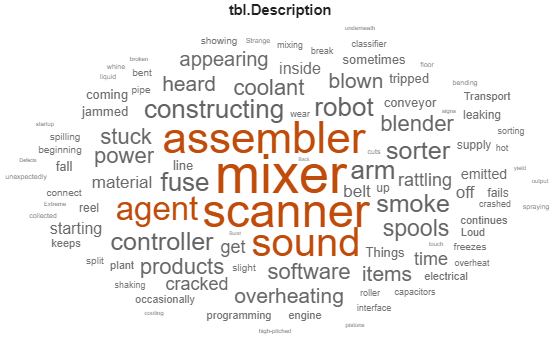

% Create wordcloud of tbl.Description
wc = wordcloud(tbl.Description);

% Add title
title("tbl.Description")

figure
wordcloud(tbl.Description);
title("Raw Data")

Live Task นี้จะสร้างตัวแปร `preprocessedText` จากคอลัมน์ข้อความในตาราง (เช่น `tbl.Description`) โดยผ่านกระบวนการต่าง ๆ เช่น:

- ลบคำฟุ่มเฟือย

- แยกคำ (tokenize)

- แปลงรูปคำ (lemmatize)

- สร้าง word cloud ฯลฯ

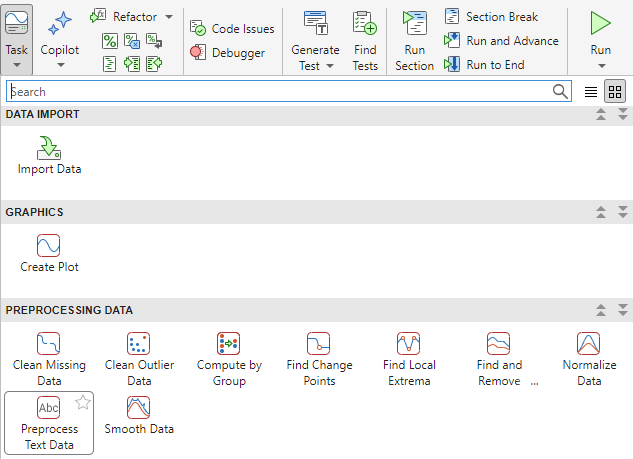

%% Preprocess Text
preprocessedText4 = tbl.Category;

% Tokenize
preprocessedText4 = tokenizedDocument(preprocessedText4);

% Add token details
preprocessedText4 = addPartOfSpeechDetails(preprocessedText4);

% Change and remove words
preprocessedText4 = normalizeWords(preprocessedText4,Style="lemma");
preprocessedText4 = removeShortWords(preprocessedText4,2);
preprocessedText4 = removeLongWords(preprocessedText4,15);
preprocessedText4 = erasePunctuation(preprocessedText4);

% Display results
display(preprocessedText4);

preprocessedText4 =   480×1 tokenizedDocument:

    2 tokens: mechanical failure
    2 tokens: mechanical failure
    2 tokens: electronic failure
    2 tokens: electronic failure
    2 tokens: electronic failure
    1 tokens: leak
    2 tokens: electronic failure
    2 tokens: mechanical failure
    2 tokens: mechanical failure
    2 tokens: mechanical failure
    2 tokens: electronic failure
    2 tokens: electronic failure
    2 tokens: software failure
    2 tokens: mechanical failure
    2 tokens: mechanical failure
    2 tokens: mechanical failure
    2 tokens: mechanical failure
    2 tokens: software failure
    2 tokens: electronic failure
    2 tokens: electronic failure
    2 tokens: mechanical failure
    2 tokens: electronic failure
    2 tokens: electronic failure
    2 tokens: software failure
    2 tokens: electronic failure
    2 tokens: mechanical failure
    2 tokens: mechanical failure
    

tokenDetails(preprocessedText4)

ans = 892×7 table
       Token        DocumentNumber    SentenceNumber    LineNumber     Type      Language    PartOfSpeech
    ____________    ______________    ______________    __________    _______    ________    ____________

    "mechanical"          1                 1               1         letters       en       adjective   
    "failure"             1                 1               1         letters       en       noun        
    "mechanical"          2                 1               1         letters       en       adjective   
    "failure"             2                 1               1         letters       en       noun        
    "electronic"          3                 1               1         letters       en       proper-noun 
 

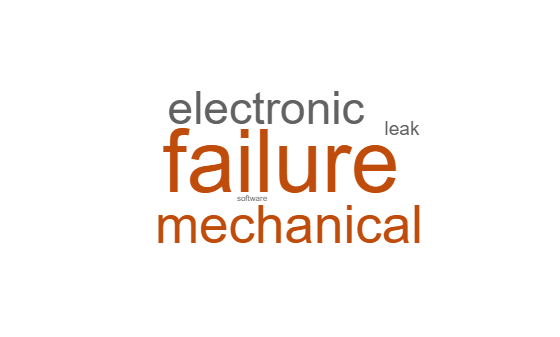

wordcloud(preprocessedText4);

## Clean Up HTML

Use the Clean up HTML options to preprocess HTML code.

Read HTML code from a web page using the webread function and view the first 300 characters.

url = "https://www.mathworks.com/products/text-analytics.html";
code = webread(url);
code(1:300)

ans =     '<!doctype html>
     <html lang="en">
     <head>
     	<meta charset="utf-8"/>
     	<meta name="viewport" content="width=device-width, initial-scale=1.0"/>
     	<meta name="description" content="Use Text Analytics Toolbox to extract, visualize, and analyze text data, and for applications like sentiment analysis, predicti'


Extract the text from the HTML by setting the **Data** option to `code` and selecting the **Extract HTML text** option. To ensure that the task includes `code` in the drop down, run the script so that `code` is in the MATLAB workspace.

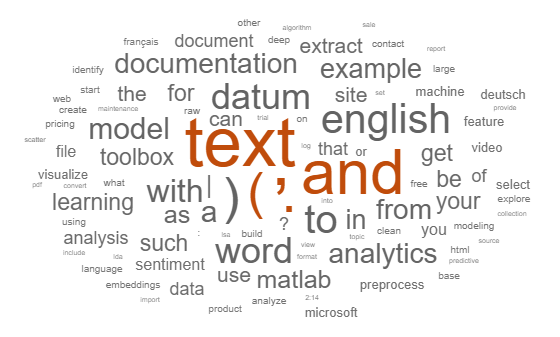

%% Preprocess Text
preprocessedText2 = code;

% Clean up HTML
preprocessedText2 = extractHTMLText(preprocessedText2);

% Tokenize
preprocessedText2 = tokenizedDocument(preprocessedText2);

% Add token details
preprocessedText2 = addPartOfSpeechDetails(preprocessedText2);

% Change and remove words
preprocessedText2 = normalizeWords(preprocessedText2,Style="lemma");

% Display results
wordcloud(preprocessedText2);

## **Change and Remove Words**

Normalize and remove words that the word normalization and stop word removal options do not support by specifying custom word lists in the **Replace words** and **Remove words** options.

Load the factory reports data.

%% Preprocess Text
preprocessedText3 = tbl.Description;

% Tokenize
preprocessedText3 = tokenizedDocument(preprocessedText3);

% Add token details
preprocessedText3 = addPartOfSpeechDetails(preprocessedText3);

% Change and remove words
preprocessedText3 = normalizeWords(preprocessedText3,Style="lemma");
preprocessedText3 = replaceNgrams(preprocessedText3,"mixer","blender",IgnoreCase=false);
preprocessedText3 = removeWords(preprocessedText3,"scanner",IgnoreCase=false);
preprocessedText3 = removeShortWords(preprocessedText3,2);
preprocessedText3 = removeLongWords(preprocessedText3,15);
preprocessedText3 = removeStopWords(preprocessedText3,IgnoreCase=false);
preprocessedText3 = erasePunctuation(preprocessedText3);

% Display results
wordcloud(preprocessedText3);